Evaluation of system properties in z domain given H(z)

B = [1,0,0];            % numerator polynomial
A = [1,-0.25,-0.375];   % denominator polynomial
ts = -1;
H1 = tf(B,A,ts,'Variable','z')

H1 =
 
          z^2
  --------------------
  z^2 - 0.25 z - 0.375
 
Sample time: unspecified
Discrete-time transfer function.



H2 = tf(B,A,ts,'Variable','z^-1')

H2 =
 
              1
  --------------------------
  1 - 0.25 z^-1 - 0.375 z^-2
 
Sample time: unspecified
Discrete-time transfer function.




% using numerator and denominator polynomials directly

% zeros are roots of numerator
roots(B)

ans =      0
     0



% poles are roots of denominator
roots(A)

ans =     0.7500
   -0.5000


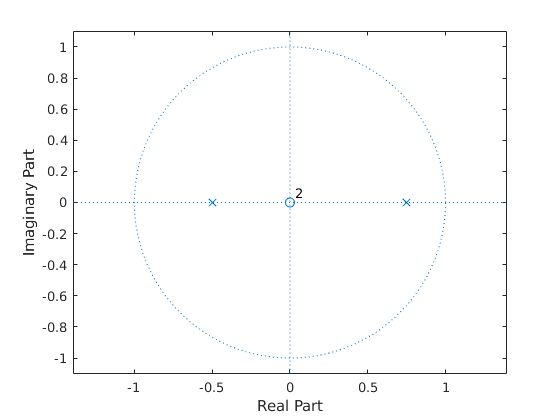


% plot poles and zeros in z plane
zplane(B,A)

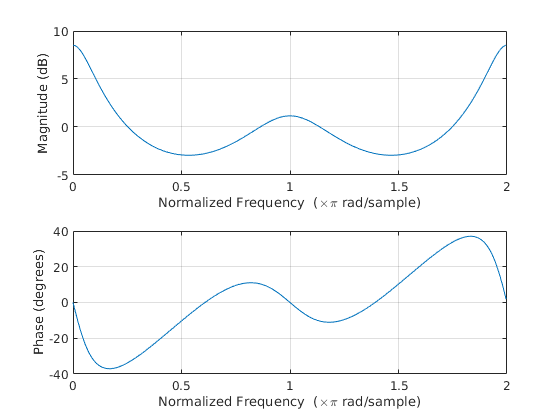


% plot frequency response of system
freqz(B,A,'whole')